# **HomeWork n.1 2021/22**

### **Camilla De Martino**

#### **0124002258**

**N.1  Definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete **`funrif`**;**


$$e^{-x} \cdot (cos(\frac {p \cdot x}{2}-\pi/2))^2 +  \frac {q}{1+2x^2}cos(2x)-3$$
  

dove *p* e *q *sono rispettivamente il numero di caratteri del mio nome e il numero di caratteri del mio cognome(si esclude lo spazio).

p = 7

q = 9

funrif = @(x) exp(-x).*(cos(7*x/2-pi/2)).^2+(9./(1+2*x.^2).*cos(2*x)-3); 

Al fine di poter visualizzare la funzione si traccia il grafico e uso il formato long per tutti i risultati.

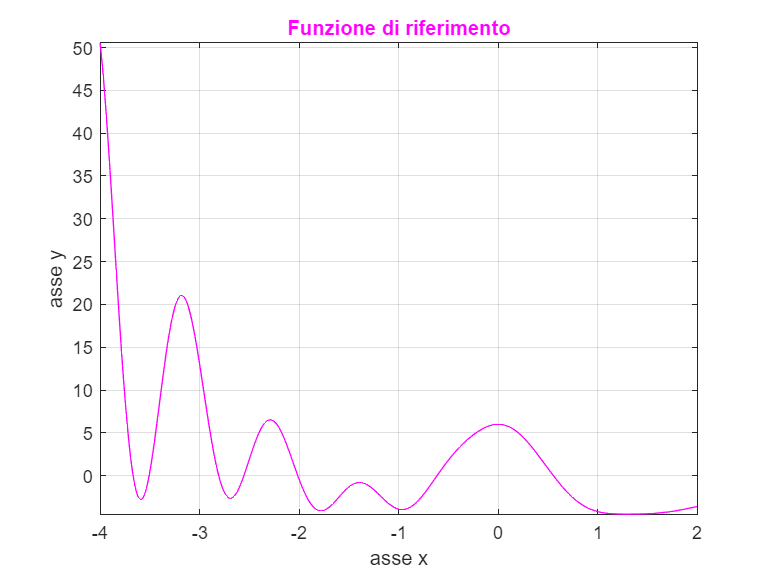

format long 
%scelgo un intervallo ampio per poter visualizzare al meglio la funzione
figure(1)
fplot(funrif, [-4, 2], 'color', 'm')

%visualizziamo la griglia e utilizzo il comando hold on per conservare il
%grafico negli assi correnti anche con l'aggiunta di altri grafici
grid on
hold on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

**N.2   Visualizzate il grafico della funzione di riferimento in **$[a,b]$**, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando **`text`**) gli estremi dell'intervallo scelto, i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *****punto di minimo 1*****), il secondo valore minimo e l'ascissa del secondo minimo (detta *****punto di minimo 2*****), il primo valore massimo e l'ascissa del primo massimo (detta *****punto di massimo 1*****), il secondo valore massimo e l'ascissa del secondo massimo (detta *****punto di massimo 2*****);**

Affinché la mia funzione possa contenere solo 5 zeri, 2 minimi e 2 massimi modifico l'intervallo iniziale definendo i nuovi estremi, per cui

a = -3.83, b = -1.85

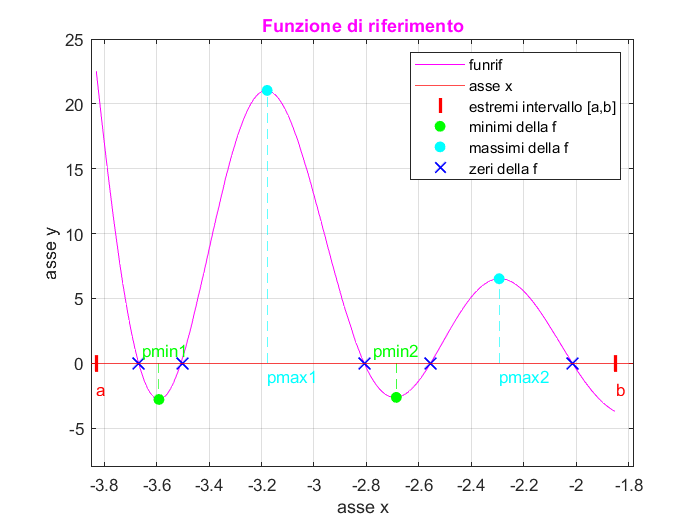

%modifico l'intervallo della funzione inizialmente scelto in flpot
%in modo che contenga i valori a e b

figure(2)
fplot(funrif, [-3.83, -1.85], 'color', 'm')

%modifico la posizione degli assi 
axis([-3.85 -1.78 -8 25]) 

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')


%passo ad evidenziare gli estremi dell'intervallo nel quale svolgerò i
%calcoli e l'asse delle x, 
%dove a = -3.83 e b = -1.85
yline(0,'-','color','r')
text(-3.83,-2,'a', 'Color', 'r');
text(-1.85,-2,'b', 'color', 'r');

plot([-3.83,-1.85],[0,0],'|','color','r', 'markersize', 10, 'LineWidth', 2)

%segno approssimativamente (osservando il grafico) i valori dei minimi, massimi e zeri
%proietto poi i punti per segnare i ripettivi punti di minimo massimo
plot([-3.59105 -2.68619], [-2.7907 -2.63135], 'o','color','g','MarkerFaceColor','g') %minimi
plot([-3.17844 -2.29396], [21.0354 6.51704], 'o', 'color', 'c', 'MarkerFaceColor','c') %massimi
plot([-3.66735 -3.50256 -2.80783 -2.55528 -2.01567], [0 0 0 0 0], 'x', 'color', 'b', 'markersize', 10, 'LineWidth', 1) %zeri

%proiezioni
plot([-3.59105 -3.59105], [0,-2], '--','color','g')  %primo punto minimo
plot([-2.68619 -2.68619], [0,-2], '--','color','g')  %secondo punto minimo
plot([-3.17844 -3.17844], [0,21], '--','color','c')  %primo punto massimo
plot([-2.29396 -2.29396], [0,6], '--','color','c')  %secondo punto massimo

%segno le proiezioni
text(-3.17844,-1,'pmax1', 'color', 'c');
text(-2.29396,-1,'pmax2', 'color', 'c');
text(-3.65685, 1,'pmin1', 'color', 'g');
text(-2.77619, 1,'pmin2', 'color', 'g');

legend('funrif', 'asse x','estremi intervallo [a,b]', 'minimi della f', 'massimi della f', 'zeri della f' )

**N.3 Usate la function Matlab **`fzero`** per determinare i 5 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte;** 

figure(3)
fplot(funrif, [-3.83, -1.85], 'color', 'm')
axis([-3.85 -1.78 -8 25])

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')
text(-3.83,-2,'a', 'Color', 'r');
text(-1.85,-2,'b', 'color', 'r');

plot([-3.83,-1.85],[0,0],'|','color','r', 'markersize', 10, 'LineWidth', 2)

Matlab ha al suo interno una funzione specifica per la ricerca degli zeri di una funzione continua, il cui algoritmo combina i metodi di bisezione, secante e newton e converge sempre. La funzione prende in input la funzione di cui si vuole calcolare lo zero e l'approssimazione iniziale della soluzione. Poiché si vogliono calcolare 5 zeri della funzione funrif, fzero verrà chiamata 5 volte e ogni volta restituirà un valore prossimo in cui la funzione si annulla.

z1_esatt = fzero(funrif, -3.66735 )

z1_esatt =   -3.668278758512967


z2_esatt = fzero(funrif, -3.50256)

z2_esatt =   -3.507369139195409


z3_esatt = fzero(funrif, -2.80783)

z3_esatt =   -2.808582396324628


z4_esatt = fzero(funrif, -2.55528)

z4_esatt =   -2.555501590097505


z5_esatt = fzero(funrif, -2.01567)

z5_esatt =   -2.014767504519396


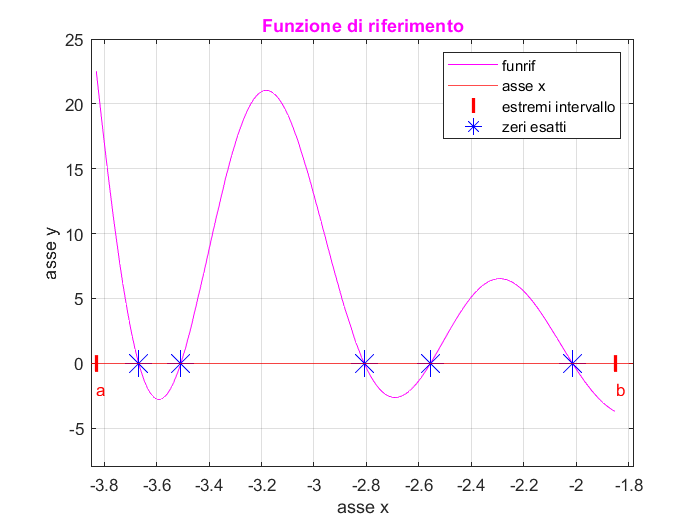

plot([z1_esatt z2_esatt z3_esatt z4_esatt z5_esatt],[0 0 0 0 0],'*','markersize',15,'color','b')
legend('funrif','asse x','estremi intervallo','zeri esatti')

**N.4 Determinate un'approssimazione dei 5 zeri, usando il metodo di bisezione (nostra function **`bisezione`**) per lo zero più piccolo, il metodo delle Secanti (nostra function **`Secanti`**) per il secondo e terzo zero  e il metodo di Newton (nostra function **`Newton`**) per il quarto e il quinto zero (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;**

Metodo di Bisezione

Il metodo di bisezione è un algoritmo globale, cioè che converge sempre se applicabile, e con velocità di convergenza lineare, l'errore si riduce di un fattore costante ad ogni passo. I requisiti necessari per l'applicabilità sono:

- la f(x) deve essere una funzione nota e continua nell'intervallo che contiene la soluzione;

- f(x) deve assumere valori di segno opposto agli estremi dell'intervallo che contiene la soluzione;

- si deve dunque possedere un'informazione che consenta di localizzare la soluzione, che può essere l'intervallo scelto.

L'algoritmo si basa sull'approccio Divide et Impera, che riduce progressivamente l'intervallo che contiene la soluzione.

%fisso la stima del massimo errore assoluto richiesto sul risultato. 
%Poiché si richiede che le prime 6 cifre frazionarie siano corrette, 
%per la legge del valore assoluto avremo
delta_ass = 1e-6;

%la function prende in input l'handle alla funzione, gli estremi
%dell'intervallo scelto e l'accuratezza che si vuole ottenere sul risultato

z1_bis = bisezione(funrif, -3.68216, -3.64448, delta_ass)

z1_bis =   -3.668278666381836


Metodo delle Secanti

Il metodo delle secanti può essere visto come una variante del metodo di Newton ma, piuttosto che utilizzare la derivata prima, fa uso di una sua approssimazione.

Esso è però un metodo locale, non converge sempre, e ha rapidità di convergenza superlineare, ossia l'ordine della convergenza è strettamente maggiore di 1 e l’errore relativo si riduce diventando una potenza dell’errore precedente. La convergenza dipende dalla f e dalle sue approssimazioni iniziali.

L'idea dell'algoritmo è quella di considerare l'intersezione della retta secante passante per i due punti (xk, f(xk)) e (xk-1, f(xk-1)) con l'asse delle x come successiva aprrosimazione, la cui pendenza è (f(xk) - f(xk-1)) /(xk - xk-1).

%fisso il numero massimo di iterazioni consentite
kmax = 7;

%la function prende in input l'handle alla funzione, 
% la prima approssimazione inziale della soluzione,
% la seconda approssimazione iniziale, 
% l'accuratezza che si vuole ottenere
% sul risultato e il numero massimo di iterazioni richieste

z2_sec = Secanti(funrif, -3.50256, -3.50736 , delta_ass, kmax)

z2_sec =   -3.507368948526300


z3_sec = Secanti(funrif, -2.80783, -2.80858, delta_ass, kmax)

z3_sec =   -2.808582403649388


Metodo di Newton

Il metodo di Newton usa i valori di f e della sua derivata prima f', è un meodo locale la cui convergenza dipende dalle condizioni iniziali scelte e ha una rapidità di convergenza quadratica. Ad ogni passo di iterazione, cioè, l'errore relativo si riduce diventando il quadrato dell'errore precedente.

L'idea dell'algoritmo è quella di approssimare ad ogni passo la f  con la retta tangente alla curva nel punto di approssimazione (xk, f(xk)). Il punto di intersezione della retta tangente con l'asse delle x sarà la successiva approssimazione. 

I requisiti per l'applicabilità sono:

- f(x) e f'(x) devono essere note

- si conosce una buona approssimazione iniziale x0

si calcoli la derivata con funtool e risulta:


$$$-\cos^2 \left(7\frac{x}{2}-\frac{\pi }{2}\right)e^{-x} -\frac{\left(18\sin \left(2x\right)\right)}{2x^2 +1}-\frac{\left(36\mathrm{xcos}\left(2x\right)\right)}{\left(2x^2 +1{\left.\right)}^2 \right.}-7\cos \left(7\frac{x}{2}-\frac{\pi }{2}\right)\sin \left(7\frac{x}{2}-\frac{\pi }{2}\right)e^{-x}$$$



$$- cos((7*x)/2 - pi/2)^2*exp(-x) - (18*sin(2*x))/(2*x^2 + 1) - (36*x*cos(2*x))/(2*x^2 + 1)^2 - 7*cos((7*x)/2 - pi/2)*sin((7*x)/2 - pi/2)*exp(-x)$$


derfunrif = @(x) - cos((7*x)/2 - pi/2).^2.*exp(-x) - (18*sin(2*x))./(2*x.^2 + 1) - (36*x.*cos(2*x))./(2*x.^2 + 1).^2 - 7*cos((7*x)/2 - pi/2).*sin((7*x)/2 - pi/2).*exp(-x);
%la funzione prende in input l'handle alla funzione 
%la derivata
%l'approssimazione iniziale della soluzione
%il massimo errore assoluto richiesto
%il numero massimo di iterazioni

z4_new = Newton(funrif, derfunrif, -2.55528, delta_ass, kmax)

z4_new =   -2.555501511261121


z5_new = Newton(funrif, derfunrif, -2.01567, delta_ass, kmax)

z5_new =   -2.014768276733989


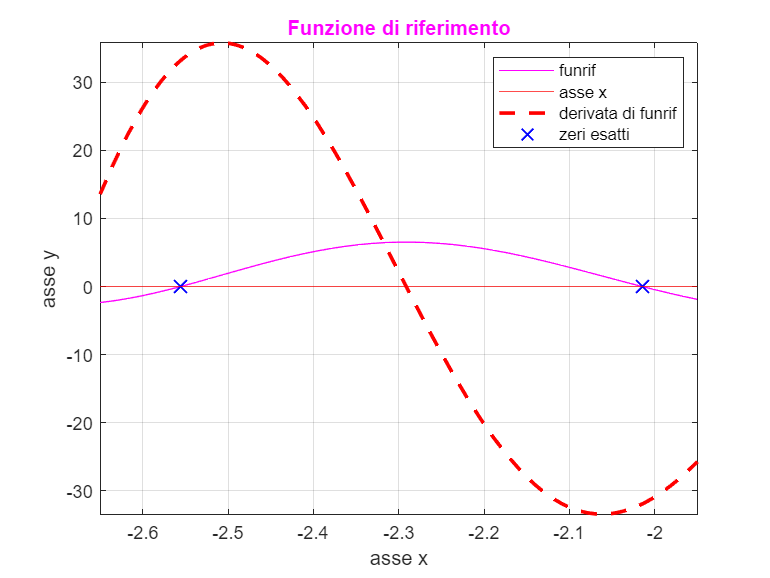

figure(4)
fplot(funrif, [-2.65, -1.95], 'color', 'm')

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')

fplot(derfunrif, [-2.65, -1.95], "--","LineWidth", 2, 'color', 'r')
plot([z4_esatt, z5_esatt],[0, 0],'x','markersize',10,'color','b', 'LineWidth', 1)

legend('funrif', 'asse x', 'derivata di funrif', 'zeri esatti')

%è possibile notare che il valore assoluto della derivata calcolato negli ultimi due
%zeri esatti, è molto più grande del valore assoluto della funzione negli
%stessi punti
abs(funrif(z4_esatt))

ans =      1.731947918415244e-14


abs(funrif(z5_esatt))

ans =      3.108624468950438e-15


abs(derfunrif(z4_esatt))

ans =   33.198991896738278


abs(derfunrif(z5_esatt))

ans =   31.936074091194030


Possiamo concludere quindi affermando che tale problema è un problema ben condizionato

**N.5  Considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con le Secanti), sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con Newton) e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei cinque zeri;**

Errore assoluto

Per il teorema dell'errore assoluto sia **x** un numero qualunque, nel nostro caso gli zeri calcolati con i vari metodi, e sia **a** una sua approssimazione iniziale, valore restituito da fzero, se x e a hanno la stessa parte intera e le stesse m cifre della parte frazionaria allora l'errore assoluto sarà minore di una potenza di 10 uguale a -m (accuratezza richiesta) 

%calcolo l'errore assoluto tra 
%l'approssimazione della BISEZIONE e la soluzione esatta

errass_bis = abs(z1_bis - z1_esatt)

errass_bis =      9.213113116857130e-08


Si noti che l'errore calcolato è minore dell'accuratezza richiesta, ma per un ulteriore precisione è possibile verificarlo con un semplice comando matlab

%è un comando di tipo logical dove 1 = vero
errass_bis < delta_ass 

ans = logical
   1


%SECANTI e soluzione esatta
errass_sec2 = abs(z2_sec - z2_esatt)

errass_sec2 =      1.906691089459400e-07


errass_sec3 = abs(z3_sec - z3_esatt)

errass_sec3 =      7.324760353810689e-09


anche in questo caso è più piccola dell'accuratezza

%verifichiamo
errass_sec2 < delta_ass

ans = logical
   1


errass_sec3 < delta_ass 

ans = logical
   1


%NEWTON e zeri esatti
errass_new4 = abs(z4_new - z4_esatt)

errass_new4 =      7.883638319938768e-08


errass_new5 = abs(z5_new - z5_esatt)

errass_new5 =      7.722145931587931e-07


Anche per gli ultimi zeri l'errore assoluto è minore di delta_ass

%verifichiamo
errass_new4 < delta_ass 

ans = logical
   1


errass_new5 < delta_ass

ans = logical
   1


Residuo

Calcolare il residuo significa quantificare la bontà dell'approssimazione della soluzione per verificare che l'errore sia minore uguale ad 1. A tal proposito calcoliamo il valore della funzione in ognuno degli zeri calcolati con i vari metodi.

%residuo BISEZIONE
residuo_bis = abs(funrif(z1_bis))

residuo_bis =      6.755005189429397e-06


Il residuo dell'approssimazione calcolato con il metodo della bisezione è dello stesso ordine di grandezza dell'accuratezza richiesta (delta_ass = 10^-6), ciò ci porta a dire che il problema è ben condizionato.

%residuo SECANTI
residuo_sec2 = abs(funrif(z2_sec))

residuo_sec2 =      1.181683359208208e-05


Ci aspettiamo che il residuo sia approssimativamente uguale all'accuratezza richiesta, poiché il residuo del secondo zero calcolato con il metodo delle secanti differisce di 1(ordine di grandezza) e l'errore tra lo zero calcolato con la secante e con fzero è minore dell'accuratezza, allora possiamo considerare il problema comunque come ben condizionato.

residuo_sec3 = abs(funrif(z3_sec))

residuo_sec3 =      3.298050743616443e-07


L'ordine di grandezza del residuo calcolato sul terzo zero è maggiore dell'ordine di grandezza dell' accuratezza, dunque il problema è ben condizionato

%residuo NEWTON
residuo_new4 = abs(funrif(z4_new))

residuo_new4 =      2.617288779926952e-06


Ancora una volta l'ordine di grandezza coincide con quello dell'accuretezza di conseguenza sarà ben condizionato

residuo_new5 = abs(funrif(z5_new))

residuo_new5 =      2.466152076019412e-05


lo consideriamo ben condizionato per le stesse osservazioni fatte sul secondo zero

Indice di condizionamento

Si può stimare quantitativamente il condizionamento di qualunque problema, ossia quanto questo è sensibile ad errori sulla funzione. Esso è dato dal rapporto dell'errore commesso sul calcolo della soluzione e sull'incertezza dei dati. 

%indice di condizionamento del metodo di BISEZIONE
kfbis = 1/abs(derfunrif(z1_esatt))

kfbis =    0.013638934818848


%indice di condizionamento del metodo delle SECANTI
kfsec2 = 1/abs(derfunrif(z2_esatt))

kfsec2 =    0.016135394541208


kfsec3 = 1/abs(derfunrif(z3_esatt))

kfsec3 =    0.022209361526266


%indice di condizionamento del metodo di NEWTON
kfnew3 = 1/abs(derfunrif(z4_esatt))

kfnew3 =    0.030121396550545


kfnew4 = 1/abs(derfunrif(z5_esatt))

kfnew4 =    0.031312552605699


Come mi aspettavo dalla figura, poiché la funzione non risulta essere piatta sull'asse delle x, gli indici di condizionamento di tutti gli zeri calcolati hanno restituito un numero prossimo allo zero confermando la mia ipotesi che il problema fosse ben condizionato.

**N.6  Osservando il grafico della vostra funzione di riferimento nell'intervallo **$[a,b]$**e della bisettrice, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function **`PFisso (suggerimento: `**usate opportunamente**` fzero)`**, calcolate una approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, cioè più vicino ad **$a$**, e determinate il residuo; dite se il metodo del punto fisso convergerebbe a tale punto fisso.**

Il problema del punto fisso si pone di trovare le ascisse del punto di intersezione del grafico della funzione g con la bisettrice del primo quadrante. Una soluzione approssimata del problema del punto fisso è calcolata dal metodo del punto fisso. Tale metodo consiste nel partire da un'approssimazione iniziale x0 e il valore della funzione calcolato in quel punto sarà considerato come la successiva approssimazione del punto fisso, procedendo dunque ricorsivamente. Si presenta però come un metodo locale, la cui convergenza dipende dalla contrazione della funzione, e con velocità di convergenza lineare, con costante di proporzionalità c data dal valore assoluto della derivata prima della funzione calcolata nel punto fisso.

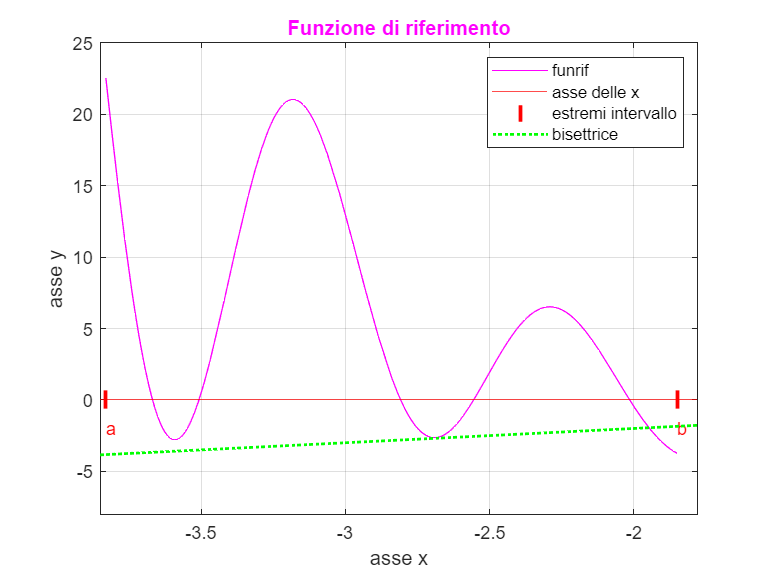

figure(5)
%definisco la bisettrice 
xx = linspace(-3.85,-1.78, 10);

fplot(funrif, [-3.83, -1.85], 'Color', 'm')
axis([-3.85 -1.78 -8 25]) 

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')
text(-3.83,-2,'a', 'color', 'r');
text(-1.85,-2,'b', 'color', 'r');
plot([-3.83,-1.85],[0,0],'|','color','r', 'markersize', 10, 'LineWidth', 2)
plot(xx,xx, 'g:', 'LineWidth', 1.5)

legend('funrif','asse delle x', 'estremi intervallo', 'bisettrice')

Si richiede di calcolare un' approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, ma è possibile notare che l'unico punto a disposizione è quello più vicino all'estremo b

figure(6)
%approssimazione inziale ad occhio
x0 = -1.94545;

il Problema di risoluzione di un'equazione può essere trasformato in un problema di punto fisso equivalente. Il problema di determinazione di uno zero f(x) = 0 può essere trasformato in un problema del punto fisso aggiungendo e sottraendo una stessa quantità f(x) - x = x dove f(x) -x è la nostra funzione g(x). I punti fissi saranno dunque gli zeri della funzione.

fpfisso = @(x) funrif(x) - x;

%calcolo lo zero più vicino all'approssimazione iniziale utilizzanfo la
%function fzero

pfisso = fzero(fpfisso, x0)

pfisso =   -1.947746021425107


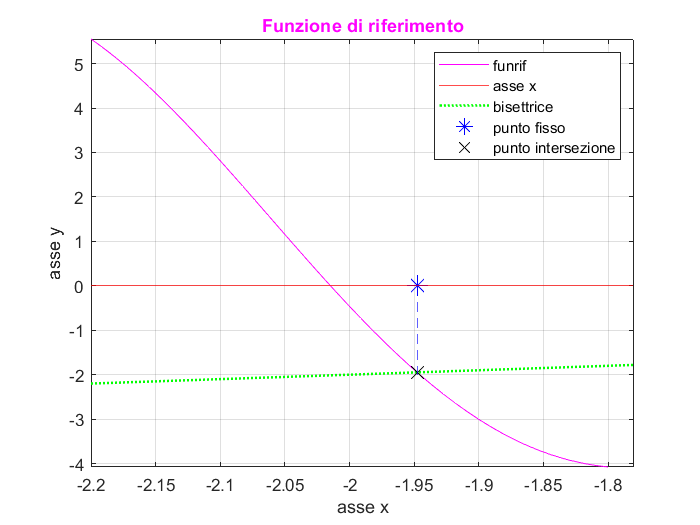

xx = linspace(-2.2,-1.78, 10);
fplot(funrif, [-2.2, -1.8], 'Color', 'm')

hold on 
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')
plot(xx,xx, 'g:', 'LineWidth', 1.5)

plot(pfisso,0,'*','markersize',11,'color','b')
plot(-1.94775,-1.95, 'x', 'MarkerSize',10, 'color', 'k')
plot([pfisso pfisso], [0 -2], '--','color','b')

legend('funrif', 'asse x', 'bisettrice', 'punto fisso', 'punto intersezione')

%calcolo del residuo
%poiché risulta che deve esssere funrif(pfisso) = pfisso allora
residuo_pf = abs(funrif(pfisso)- pfisso)

residuo_pf =      6.883382752675971e-15


Il valore ottenuto è molto piccolo per cui è ben condizionato il problema, si noti infatti che la funzione e la bisettrice hanno pendenze diverse

Convergenza

Abbiamo detto che la convergenza dipende dalla contrazione, ossia quanto l'intervallo è "stretto", il codominio è più piccolo del dominio. Dal punto di vista visivo è semplice notare che il metodo nel punto calcolato non converge

Per una maggior sicurezza, poiché la funzione è derivabile, bisogna calcolare il valore della derivata in quel punto e vedere se risulta essere minore di 1

%eseguiamo quetso processo tramite un operazione logica
abs(derfunrif(pfisso)) < 1

ans = logical
   0


ha restituito 0 quindi falso, è maggiore di 1 e quindi diverge.

**N.7 Usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in **$[a,b]$**, con quattro chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo);**

In matlab esiste una function fminbnd per calcolare i punti di minimo intesi come le ascisse in cui la funzione assume valore minimo, a cui occorre passare l'handle alla funzione obiettivo e l'intervallo che contiene la soluzione. Poiché si vogliono calcolare i punti di minimo in un dominio in cui è definita la funzione, essi vengono detti punti di minimo locale.

L'accuratezza di default fornita da fminbnd è 10^-6, per modificarla usiamo `optimset('TolX',nuova accuratezza)).`

%primo minimo
xmin1 = fminbnd(funrif, -3.64, -3.54, optimset('TolX', 1e-10))

xmin1 =   -3.591109188158420


%secondo minimo
xmin2 = fminbnd(funrif, -2.76, -2.62, optimset('TolX', 1e-10))

xmin2 =   -2.690962934930251


In maniera analoga è possibile calcolare il punto di masssimo locale di una funzione, perché esso, attraverso considerazioni matematiche, coincide con punto minimo di una funzione con segno opposto.

%definisco quindi una nuova funzione che è l'opposto di funrif
maxfunrif = @(x) -funrif(x);

%i punti di massimo saranno calcolati analogamente con la stessa function
%di matlab

%primo massimo
xmax1 = fminbnd(maxfunrif, -3.22, -3.11, optimset('TolX', 1e-10))

xmax1 =   -3.181591399262294


%secondo massimo
xmax2 = fminbnd(maxfunrif, -2.34, -2.23, optimset('TolX', 1e-10))

xmax2 =   -2.291302107884179


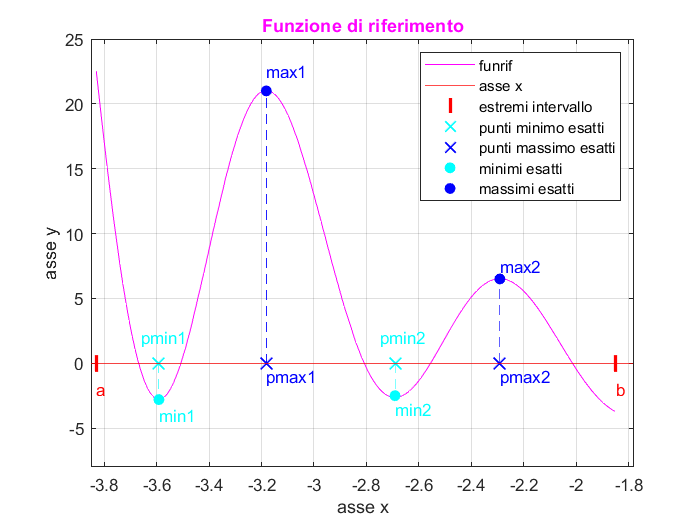

figure(7)

fplot(funrif, [-3.83, -1.85], 'Color', 'm')
axis([-3.85 -1.78 -8 25]) 

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')
text(-3.83,-2,'a', 'color', 'r');
text(-1.85,-2,'b', 'color', 'r');
plot([-3.83,-1.85],[0,0],'|','color','r', 'markersize', 10, 'LineWidth', 2)

%riporto i minimi
plot([xmin1 xmin2], [0 0], 'x','color','c','MarkerSize', 10, 'LineWidth', 1)  

%riporto i massimi
plot([xmax1 xmax2], [0 0], 'x','color','b','MarkerSize', 10, 'LineWidth', 1)

%per poter visualizzare i minimi e massimi sulla funzione segno le
%proiezioni
plot([xmin1 xmin2], [-2.8 -2.5], 'o','color','c','MarkerFaceColor','c' )
plot([xmax1 xmax2], [21 6.5], 'o','color','b','MarkerFaceColor','b' )

plot([xmin1 xmin1], [0 -2.8], '--','Color', 'c')
plot([xmin2 xmin2], [0 -2.5], '--', 'Color', 'c')
plot([xmax1 xmax1], [0 21], '--', 'Color', 'b')
plot([xmax2 xmax2], [0 6.5], '--', 'Color', 'b')

text(xmax1,-1,'pmax1', 'color', 'b');
text(xmax2,-1,'pmax2', 'color', 'b');
text(-3.66, 2,'pmin1', 'color', 'c');
text(-2.75, 2,'pmin2', 'color', 'c');

text(xmax1, 22.5,'max1', 'color', 'b');
text(xmax2, 7.5,'max2', 'color', 'b');
text(xmin1, -4,'min1', 'color', 'c');
text(xmin2, -3.5,'min2', 'color', 'c');

legend('funrif', 'asse x', 'estremi intervallo', 'punti minimo esatti', 'punti massimo esatti','minimi esatti', 'massimi esatti')

**N.8 Verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando **`axis([xmin xmax ymin ymax])`** ), e usando la **`fzero`** per calcolare tutti gli zeri della derivata; commentate i risultati ottenuti;**

Dalla matematica sappiamo che per il **teorema di Fermat** una funzione che ammette un massimo o minimo relativo o assoluto in un punto, e che sia derivabile, ha necessariamente la derivata prima nulla nel punto. 

A tal proposito verifichiamo che gli zeri della derivata della funzione funrif siano i punti di minimo e massimo calcolati. Utilizzaremo fzero per calcolare tutti gli zeri della derivata.

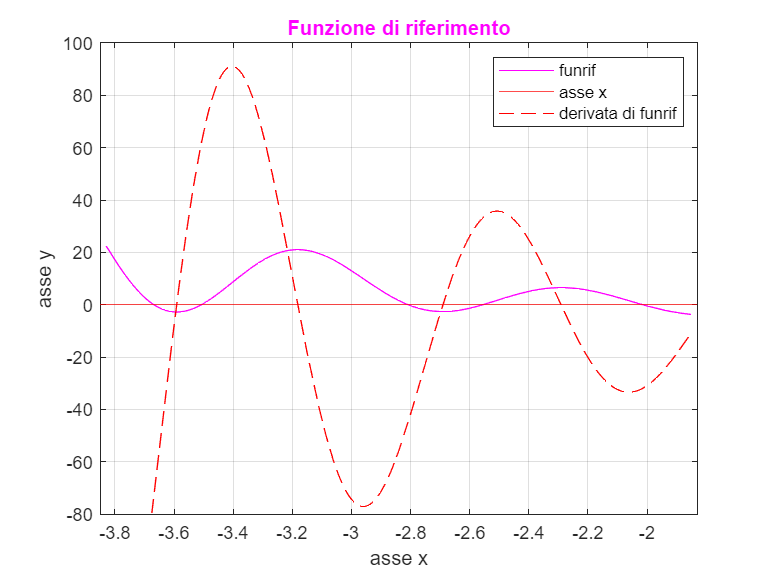

%per poter utilizzare la fzero ho bisogno di approssimazioni iniziali per
%cui visualizzo il grafico per poter calcolare ad occhio i punti

figure(8)

fplot(funrif, [-3.83, -1.85], 'Color', 'm')

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')

fplot(derfunrif,[-3.83, -1.85],'-- ','color', 'r')
axis([-3.85 -1.83 -80 100]) 

legend('funrif', 'asse x','derivata di funrif')

z1_der = fzero(derfunrif, -3.59198 ) %dovrebbe coincidere con il primo punto di minimo calcolato

z1_der =   -3.591109184950364


z2_der = fzero(derfunrif, -3.18229 ) %dovrebbe coincidere con il primo punto di massimo calcolato

z2_der =   -3.181591402088221


z3_der = fzero(derfunrif, -2.68927 ) %dovrebbe coincidere con il secondo punto di minimo calcolato

z3_der =   -2.690962922019390


z4_der = fzero(derfunrif, -2.29312) %dovrebbe coincidere con il secondo punto di massimo calcolato

z4_der =   -2.291302107798489


Visulizziamo graficamente quanto differiscono

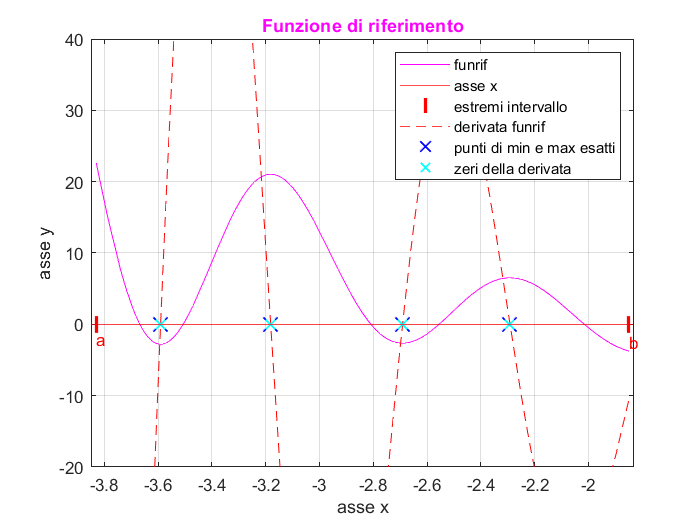

figure(9)

fplot(funrif, [-3.83, -1.85], 'Color', 'm')

hold on
grid on

title("Funzione di riferimento", 'Color','m', 'Fontname', 'Arial')
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')

yline(0,'-','color','r')
text(-3.83,-2,'a', 'color', 'r');
text(-1.85,-2.5,'b', 'color', 'r');
plot([-3.83,-1.85],[0,0],'|','color','r', 'markersize', 10, 'LineWidth', 2)

fplot(derfunrif,[-3.83, -1.85],'--','color', 'r')
axis([-3.85 -1.83 -20 40]) 

plot([xmin1 xmin2 xmax1 xmax2], [0 0 0 0], 'x','MarkerSize', 12, 'color', 'b', 'LineWidth', 1)
plot([z1_der z2_der z3_der z4_der], [0 0 0 0], 'x','MarkerSize', 8, 'color', 'c', 'LineWidth',1)

legend ('funrif','asse x', 'estremi intervallo', 'derivata funrif', 'punti di min e max esatti', 'zeri della derivata')

Si nota quindi anche graficamente che i risultati sono quasi coincidenti per cui a variare sarà la loro parte frazionaria poiché dipende fortemente dall'accuratezza ossia 10^-6 nonostante noi l'avessimo cambiata.

**N.9 Determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due minimi, e il metodo di Golden search (nostra function **`fmingolden`**) per i due massimi, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette; **

Il metodo della ricerca di fibonacci e il metodo della ricerca basato sulla sezione aurea, possono essere descritti in termini di intervalli che "racchiudono" la soluzione e sono molto efficienti. Essi, infatti, fanno uso di funzioni unimodali, funzioni con un unico punto di minimo. Una funzione f(x) è unimodale in [a,b] se esiste un unico numero** p **in tale intervallo tale che f(x) è strettamente decrescente in [a,**p**] e strettamente crescente in [**p**,b].

Il metodo di Fibonacci calcola i numeri di fibonacci da 1 a N e sceglie due punti all'interno dell'intervallo [a,b] utilizzando i numeri di fibonacci. Ad ogni passo si considera sempre una porzione più piccola che contenta la soluzione.

In matlab il metodo di Fibonacci è implementato tramite la function fminfibo,e noi useremo un'accuratezza uguale a 10^-3 (sono richieste che le prime 3 cifre frazionarie siano corrette).

%essa prende in input l'handle alla funzione
%gli estremi dell'intervallo che contiene la soluzione (ossia l'unico punto
%di minimo)
%e l'accuratezza richiesta delta_ass = 1e-3

%primo punto di minimo
minfibo1 = fminfibo(funrif, -3.65, -3.54, 1e-3 )

minfibo1 =   -3.590147058823529


%secondo punto di minimo
minfibo2 = fminfibo(funrif, -2.75, -2.64, 1e-3 )

minfibo2 =   -2.690147058823530


Il metodo della ricerca basato sulla sezione aurea (golden search) può essere considerato come una variante del metodo di fibonacci. Esso si basa sui risultati noti dei numeri di fibonacci. Si dimostra infatti che la sezione aurea è uguale al limite di n che tende all'infinito del rapporto tra l' n-esmio numero di fibonacci e il suo precedente. Viene dunque eseguito il problema in maniera del tutto analoga.

In matlab il metodo è implementato tramite la function fmingolden, che prende in input gli stessi parametri della fminfibo.

%poiché stiamo calcolando i punti di massimo l'handle alla funzione sarà
%l'inversa di funrif

%primo punto di massimo
maxgolden1 = fmingolden(maxfunrif, -3.23, -3.12, 1e-3 )

maxgolden1 =   -3.181748083032494


maxgolden2 = fmingolden(maxfunrif, -2.33, -2.23, 1e-3 )

maxgolden2 =   -2.291396867937201


**N.10  Considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati;**

ricordiamo che l'accuratezza nel nostro caso è 10^-3 e ci aspettiamo che in tutti e quattro casi sia minore.

%errore assoluto tra la GOLDEN SEARCH e il PRIMO MASSIMO ESATTO
errass_gold1 = abs(maxgolden1 - xmax1)

errass_gold1 =      1.566837701996171e-04


%errore assoluto tra la GOLDEN SEARCH e il SECONDO MASSIMO ESATTO
errass_gold2 = abs(maxgolden2 - xmax2)

errass_gold2 =      9.476005302122559e-05


%eseguo dei controlli logici per un ulteriore conferma
errass_gold1 < 1e-3

ans = logical
   1


errass_gold2 < 1e-3

ans = logical
   1


La mia ipotesi è difatti confermata

%errore assoluto tra il METODO DI FIBONACCI e il PRIMO MINIMO ESATTO
errass_gold3 = abs(minfibo1 - xmin1)

errass_gold3 =      9.621293348911486e-04


%errore assoluto tra il MOTODO DI FIBONACCI e il SECONDO MINIMO ESATTO
errass_gold4 = abs(minfibo2 - xmin2)

errass_gold4 =      8.158761067211806e-04


%verifica con comandi logici
errass_gold3 < 1e-3

ans = logical
   1


errass_gold4 < 1e-3

ans = logical
   1


Anche per il metodo di fibonacci l'errore risulta minore dell'accuratezza